# Basic Signal Analysis

Record the sentence: "She has a watch thin as a dime." using 44100 sample rate. Please try to enunciate clearly as if you are a BBC announcer. We will use this sentence in further work.

Put your code here:

Fs = 44100;
recorder = audiorecorder(Fs,16,1);
disp('Recording has started');

Recording has started


recordblocking(recorder, 5);
disp('Recording Stopped');

Recording Stopped


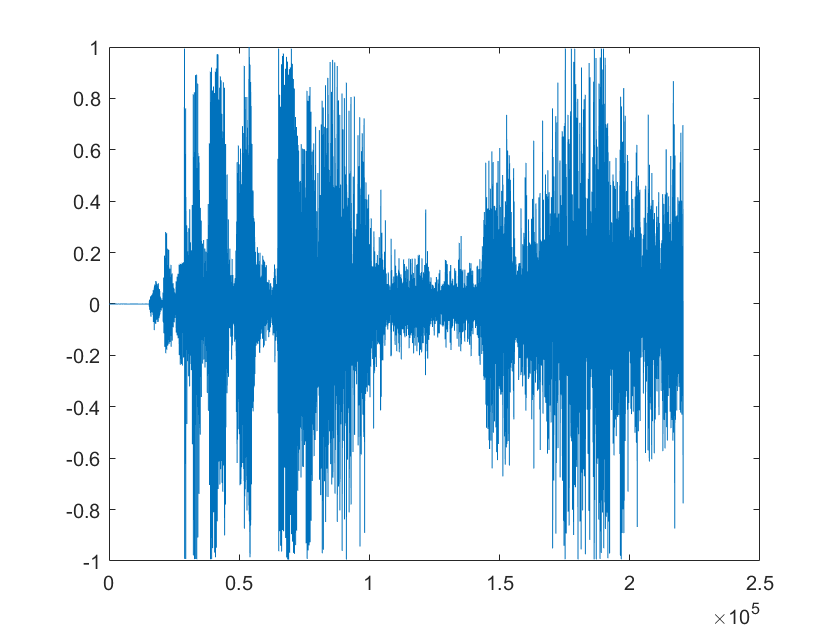

voicedata = getaudiodata(recorder);
plot(voicedata);

Window your recorded signal in the time domain. This means to remove noise or zeros at the start and end of the signal. You can do this by plotting your signal to see its time extent. You can zoom in to see where the signal starts and ends. You can then select a restricted portion of the signal which removes the rubbish at the start and end of the signal. You should also listen to the signal.

Put your code here:

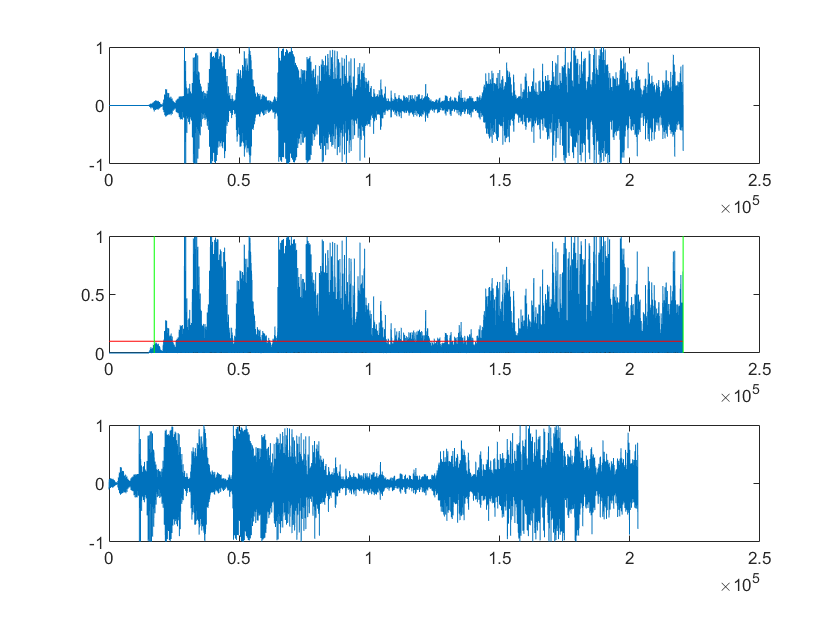

audio_mag = abs(voicedata);


bgNoiseThresh = 0.1;
%find points above noise
loudPoints = audio_mag > bgNoiseThresh;
startPoint = find(loudPoints, 1, 'first');
endPoint = find(loudPoints, 1, 'last');


windowedVoice = voicedata(startPoint:endPoint);

subplot(3,1,1);
plot(voicedata);
subplot(3,1,2);

plot(audio_mag);
line([1,length(audio_mag)], [bgNoiseThresh, bgNoiseThresh], 'Color', 'Red');
line([startPoint, startPoint],[0, max(audio_mag)], 'Color', 'Green');
line([endPoint, endPoint],[0, max(audio_mag)], 'Color', 'Green');


subplot(3,1,3);
plot(windowedVoice);

figure;

Save your time windowed signal as a wave file and upload with your lab solution.

Put your code here:

audiowrite('lab2audio.wav',windowedVoice,Fs);

## Filtering Signals

**FIR Filters**

Finite Impulse Response filters are finite sequences that correspond to the impulse response of some physical or theoretical system. Mathematically, they are described by a causal, stable sequence.

Filtering a signal with an FIR filter simulates the action of the physical or theoretical system. Let's demonstrate this. 

Consider the acoustic impulse response of a church. It could be measured using a log sine sweep or in the olden days it could be measured with a blank gun shot or the pop of a balloon.

Run the code below.

[churchIR, fsIR] = audioread('ChurchImpulseResponse-16-44p1-mono-5secs.wav');
soundsc(churchIR, fsIR);
fh = figure; set(gcf,'Visible','On');
tIR = (0:length(churchIR)-1).'/fsIR ;
plot(tIR,churchIR)

What did the impulse response sound like?

Put your answer here:

A reverberating echo, as if a heavy book was dropped in an empty hall

Let's now filter our recorded sentence with the church impulse response. This will make it seem like the speech was recorded inside the church! 

Use the Matlab function filter to filter your recorded signal with the church impulse response.

Play the filtered audio signal. It should now sound as if it was recorded in a church!

Put your code here:

churchyVoice = filter(churchIR, 1, windowedVoice);

%soundsc(windowedVoice, Fs);
soundsc(churchyVoice, fsIR);


Since we just introduced a room impulse response, we might as well speak a little bit about room acoustics. 

Sound waves in air travel at roughly 345 m/s. Shortly after the arrival of the direct sound, a series of semi-distinct reflections arrive from various reflecting surfaces (walls, floor and ceiling). These early reflections are defined to occur within 50 to 80 milliseconds. Early reflections are not heard as separate from the direct sounds and instead reinforce the direct sound. For a rapidly varying sound such as speech the limit is closer to 50 ms while for singing and music the limit is closer to 80 ms. In other words, the concept of the early reflections is related to sound perception.

Studies have shown (e.g., Leo Beranek, 1962) that a church or concert hall is considered intimate if the delay time between the direct and first reflected sound is less than 20 ms.

Reflections that arrive after the early reflections are typically lower in amplitude and closely spaced in time. These reflections are often referred to as the late reverberation or late reflections.

The reverberation time (RT60) is generally defined as the time for the reverberant sound to decrease by 60 dB from its original level and varies with frequency.

Let's play around with these ideas. First, we will plot the early reflection period.

Plot the early reflection period of the church impulse response.

Then, zero out the early reflections in the impulse response and re-filter the recorded sound with the modified church impulse response. Play the new audio signal. You should get the impression that the direct sound is somehow lessened.

Put your code here:

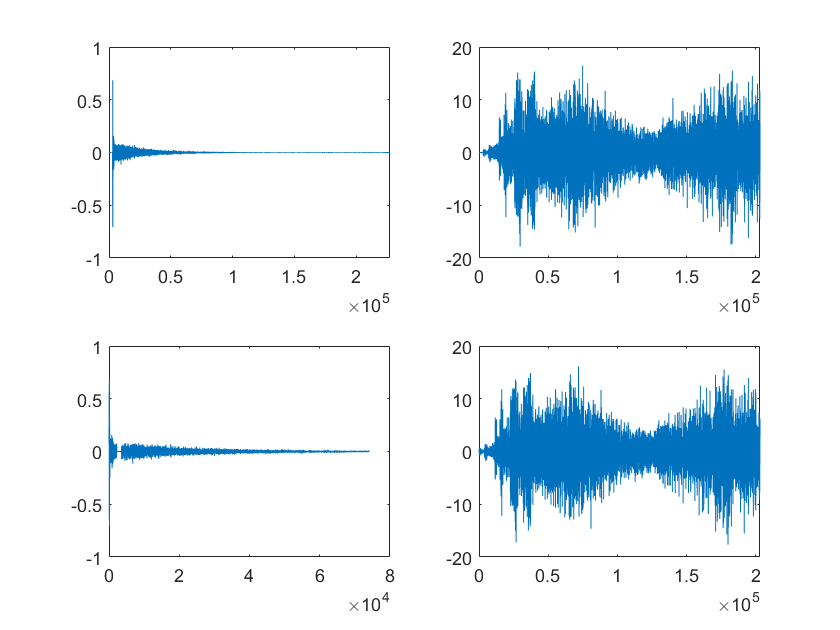

bgNoiseThresh = 0.01;
%find points above noise
churchLoudPoints = churchIR > bgNoiseThresh;
startPoint = find(churchLoudPoints, 1, 'first');
endPoint = find(churchLoudPoints, 1, 'last');
windowedChurch = churchIR(startPoint:endPoint);
tIR = (0:length(windowedChurch)-1).'/fsIR ;

%early reflection index
earlytIRLogical = (tIR > 0.050 & tIR < 0.080);

noEarlyChurchIR = windowedChurch .*(1-earlytIRLogical);
voiceNoEarly = filter(noEarlyChurchIR,1,windowedVoice);
soundsc(voiceNoEarly, fsIR)
%soundsc(churchyVoice,fsIR)
figure;
subplot(2,2,1);
plot(churchIR);
subplot(2,2,2);
plot(churchyVoice);
subplot(2,2,3);
plot(noEarlyChurchIR);
subplot(2,2,4);
plot(voiceNoEarly);

Repeat the above, but now keep the early reflections and remove the late reverberation. Re-filter the recorded sound, play the new audio signal. The reverberation should now be lessened.

Put your code here:

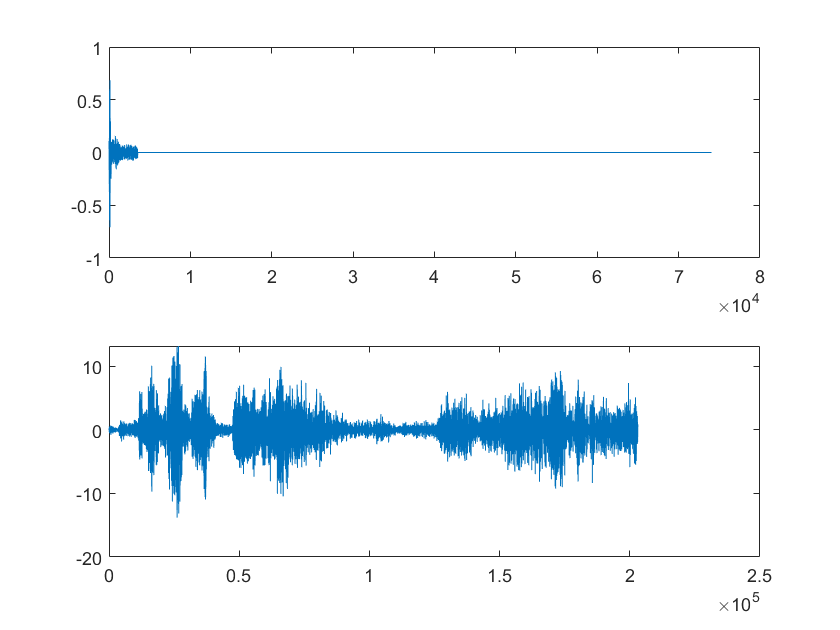

latetIRLogical = (tIR > 0.080);
noLateChurchIR = windowedChurch .*(1-latetIRLogical);
noLateVoice = filter(noLateChurchIR,1,windowedVoice);
figure;
subplot(2,1,1)
plot(noLateChurchIR);
subplot(2,1,2);
plot(noLateVoice);

soundsc(noLateVoice,fsIR);
%soundsc(windowedVoice,fsIR)

# Truncated Ideal Low-Pass Filter

Create an ideal truncated low-pass filter based on the following formula


$$H(e^{j\,\omega}) = \left\{\begin{array}{ll}
1\cdot e^{-j\,\alpha\,\omega}\text{,} & |\omega| \lt \omega_c \\
0\text{,} & \omega_c < |\omega| \le \pi
\end{array}$$


## Compute the Analytic Solution for the impulse response below:

Show your work using latex equations below.

Put work here:


$$h\left\lbrack n\right\rbrack =\frac{1}{2\pi }\int_{-\pi }^{\pi } H\left(e^{j\omega } \right)e^{j\omega n} d\omega =\frac{1}{2\pi }\int_{-\pi }^{\pi } \textrm{rect}\left(\frac{\omega }{2\omega_c }\right)e^{-j\alpha \omega } e^{j\omega n} d\omega$$



$$h\left\lbrack n\right\rbrack =\frac{1}{2\pi }\int_{-\omega_c }^{\omega_c } e^{j\omega \left(n-a\right)} d\omega =\frac{1}{\pi \left(n-a\right)}\left\lbrack \frac{\left(e^{j\omega_c \left(n-a\right)} -e^{-j\omega_c \left(n-a\right)} \right)}{2j}\right\rbrack$$



$$h\left\lbrack n\right\rbrack =\frac{\sin \left(\omega_c \left(n-a\right)\right)}{\pi \left(n-a\right)} =\frac{\omega_c}{\pi}sinc(\omega_c(n-a))$$


Determine and plot the truncated impulse response 


$$h[n] \ \text{for} \ 0 \le n < N-1$$


using N = 61, $\alpha = 30$. Choose $\omega_c$ so that the cut-off frequency is 1500 Hz.

Put your code here

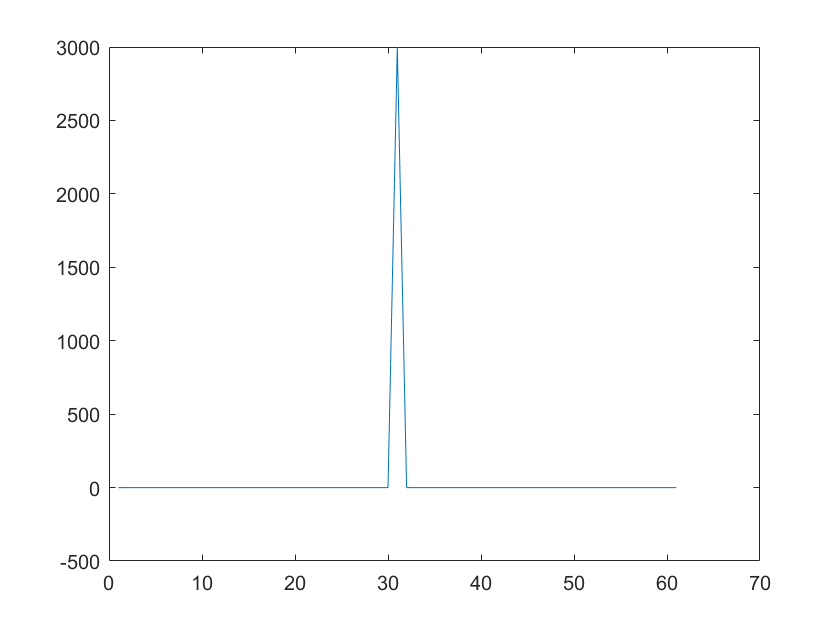

alpha = 30;
N = 61;
f_c = 1500;
nvec = [0:N-1];
omega_c = 2*pi*f_c;
truncLpIR = (omega_c/pi)*sinc((omega_c.*(nvec - alpha)));

plot(truncLpIR);

Filter your recorded speech signal with the truncated low-pass filter and play the resulting signal.

Put your code here

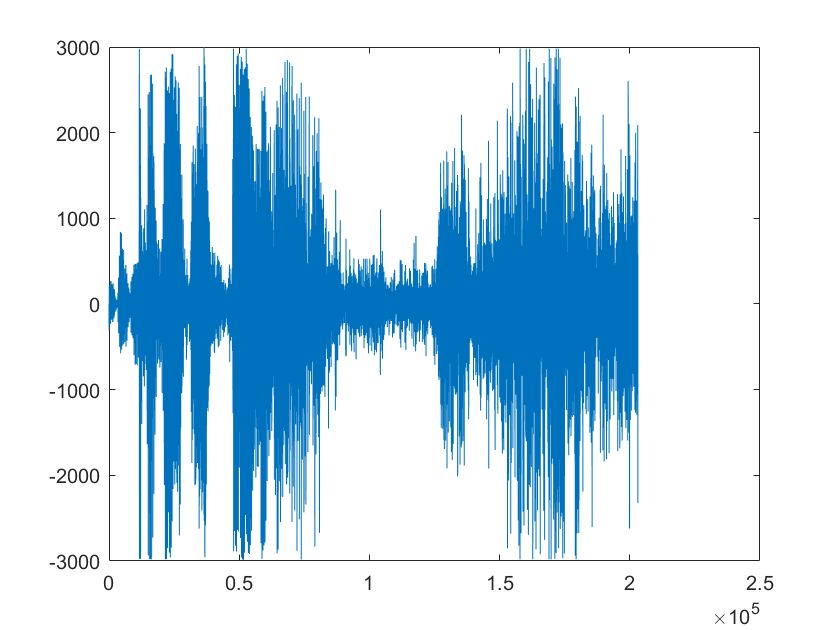

lpVoice = filter(truncLpIR,1,windowedVoice);
plot(lpVoice)

soundsc(lpVoice, Fs);

# Truncated Ideal High-Pass Filter

Create an ideal truncated low-pass filter based on the following formula


$$H(e^{j\,\omega}) = \left\{\begin{array}{ll}
1\cdot e^{-j\,\alpha\,\omega}\text{,} & \omega_c < |\omega| \le \pi \\
0\text{,} & |\omega| \le \omega_c
\end{array}$$


## Compute the Analytic Solution for the impulse response below:

Show your work using latex equations below.

Put work here:


$$\begin{array}{l}
h\left\lbrack n\right\rbrack =\frac{1}{2\pi }\int_{-\pi }^{\pi } H\left(e^{j\omega } \right)e^{j\omega n} d\omega =\frac{1}{2\pi }\int_{-\pi }^{-w_c } e^{-j\alpha \omega } e^{j\omega n} d\omega +\frac{1}{2\pi }\int_{w_c }^{\pi } e^{-j\alpha \omega } e^{j\omega n} d\omega \\
h\left\lbrack n\right\rbrack =\frac{1}{2\pi }\int_{-\pi }^{-w_c } e^{j\omega \left(n-a\right)} d\omega +\frac{1}{2\pi }\int_{w_c }^{\pi } e^{j\omega \left(n-a\right)} d\omega \\
h\left\lbrack n\right\rbrack =\frac{1}{2\pi }\left\lbrack \frac{\left(e^{-{j\omega }_c \left(n-a\right)} -e^{-j\pi \left(n-a\right)} \right)}{j\left(n-a\right)}\right\rbrack +\frac{1}{2\pi }\left\lbrack \frac{\left(e^{j\pi \left(n-a\right)} -e^{j\omega_c \left(n-a\right)} \right)}{j\left(n-a\right)}\right\rbrack \\
h\left\lbrack n\right\rbrack =\frac{1}{\pi \left(n-a\right)}\left\lbrack \frac{\left(e^{j\pi \left(n-a\right)} -e^{-j\pi \left(n-a\right)} \right)}{2j}-\frac{\left(e^{j\omega_c \left(n-a\right)} -e^{-{j\omega }_c \left(n-a\right)} \right)}{2j}\right\rbrack \\
h\left\lbrack n\right\rbrack =\frac{1}{\pi \left(n-a\right)}\left\lbrack \mathrm{sin}\left(\pi \left(n-a\right)\right)-\mathrm{sin}\left(\omega_c \left(n-a\right)\right)\right\rbrack 
\end{array}\\
h[n] = sinc(\pi(n-a)) - \frac{\omega_c}{\pi}sinc(\omega_c(n-a))$$


Determine and plot the truncated impulse response 


$$h[n] \ \text{for} \ 0 \le n < N-1$$


using N = 61, $\alpha = 30$. Choose $\omega_c$ so that the cut-off frequency is 1500 Hz.

Put your code here

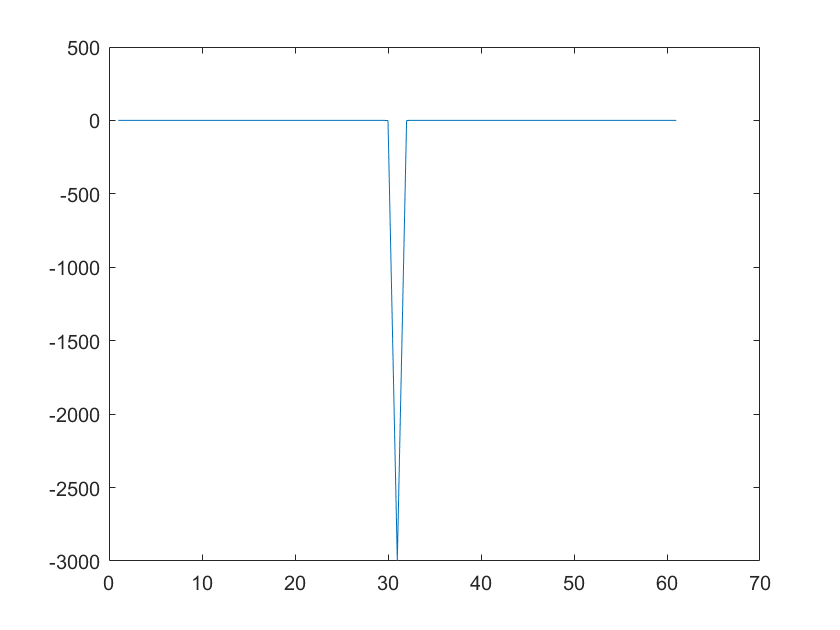

alpha = 30;
N = 61;
f_c = 1500;
nvec = [0:N-1];
omega_c = 2*pi*f_c;
truncHpIR = sinc(pi.*(nvec - alpha)) - (omega_c/pi)*sinc(omega_c.*(nvec - alpha));
figure;
plot(truncHpIR);

Filter your recorded speech signal with the truncated low-pass filter and play the resulting signal.

Put your code here

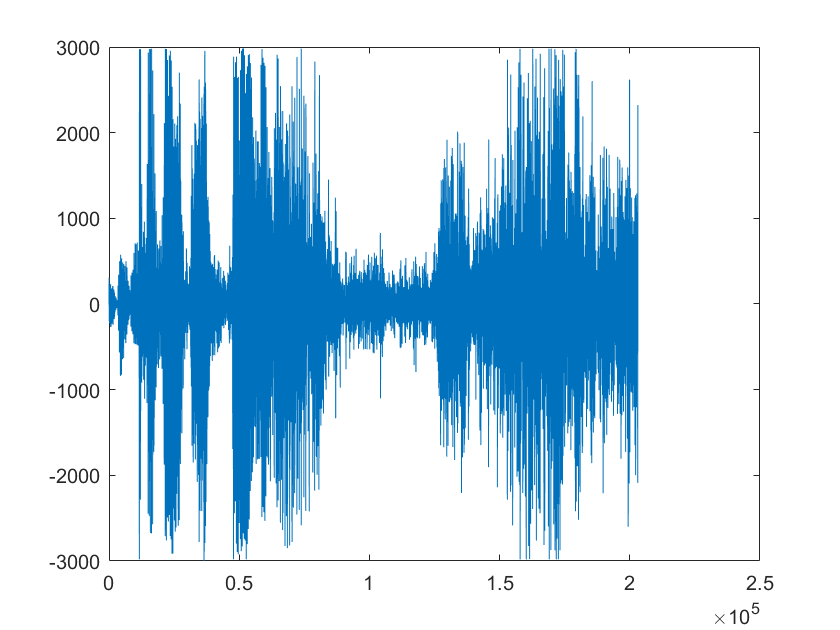

hpVoice = filter(truncHpIR,1,windowedVoice);
plot(hpVoice)

soundsc(hpVoice,fsIR)

# Create a DTFT Matlab Function

Use the example code given in class to create a MATLAB function the computes the DTFT of a finite-duration signal.  The function should have the following format

function Xfq = dtft(xn, n, omega)

% xn is finite duration signal over n

% n is the sample position vector

% omega is the frequency location vector

Upload your function as part of the lab solution.

# DTFT of Window Function

Use your DTFT function to compute the DTFT of the following window functions:

Rectangular $R_{M}[n] = \left\{\begin{array}{ll}
                          1\, \text{,} & 0 \le n < M \\
                          0\, \text{,} & \text{otherwise}                         
\end{array}$

Hanning $C_{M}[n] = 0.5\left[1 - \cos\left(\frac{2\,\pi\,n}{M-1}\right)\right]R_{M}[n]$

Triangular $T_{M}[n] = \left[1- \frac{|M-1-2\,n|}{M-1}\right]R_{M}[n]$

Hamming $H_{M}[n] = \left[0.54 - 0.46\cos\left(\frac{2\,\pi\,n}{M-1}\right)\right]R_{M}[n]$

Let M vary from 10, 25, 50, 101. Normalise the DTFT by dividing by its magnitude. 

Plot the normlized DTFT as a function of M for each of the window functions. Use the subplot function.

Put your code here:

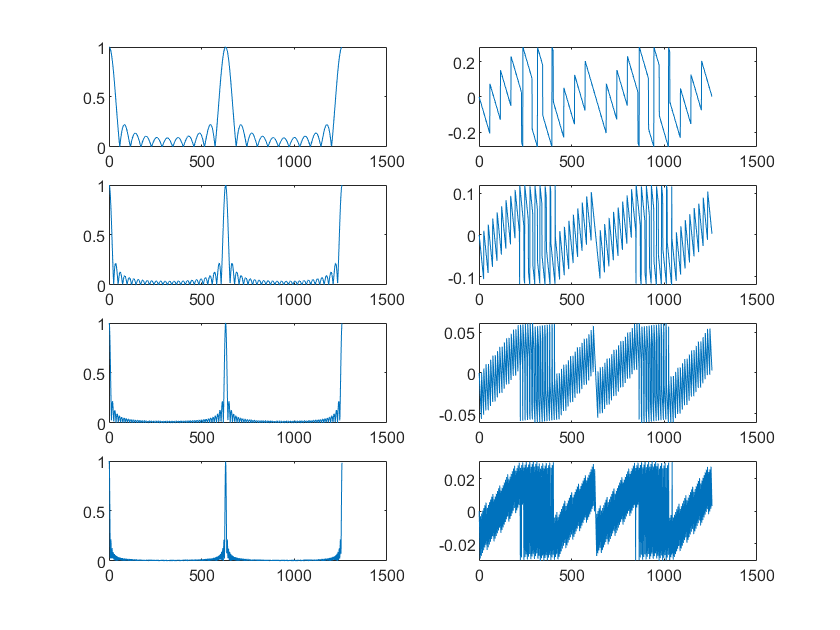

omega = [-2*pi:0.01:2*pi];
n = [-1000:1:1000];
Z = zeros(1,2001);
R_10 = Z;
R_10(1000:1010) = 1;
R_25 = Z;
R_25(1000:1025) = 1;
R_50 = Z;
R_50(1000:1050) = 1;
R_101 = Z;
R_101(1000:1101) = 1;

figure;
subplot(4,2,1);
title("R10 Magnitude");
plot(abs(dtft(R_10,n,omega))/abs(dtft(R_10,n,[0])));
subplot(4,2,2);
title("R10 Phase");
plot(angle(dtft(R_10,n,omega))/abs(dtft(R_10,n,[0])));
subplot(4,2,3);
title("R25 Magnitude");
plot(abs(dtft(R_25,n,omega))/abs(dtft(R_25,n,[0])));
subplot(4,2,4);
title("R25 Phase");
plot(angle(dtft(R_25,n,omega))/abs(dtft(R_25,n,[0])));
subplot(4,2,5);
title("R50 Magnitude");
plot(abs(dtft(R_50,n,omega))/abs(dtft(R_50,n,[0])));
subplot(4,2,6);
title("R50 Phase");
plot(angle(dtft(R_50,n,omega))/abs(dtft(R_50,n,[0])));
subplot(4,2,7);
title("R101 Magnitude");
plot(abs(dtft(R_101,n,omega))/abs(dtft(R_101,n,[0])));
subplot(4,2,8);
title("R101 Phase");
plot(angle(dtft(R_101,n,omega))/abs(dtft(R_101,n,[0])));

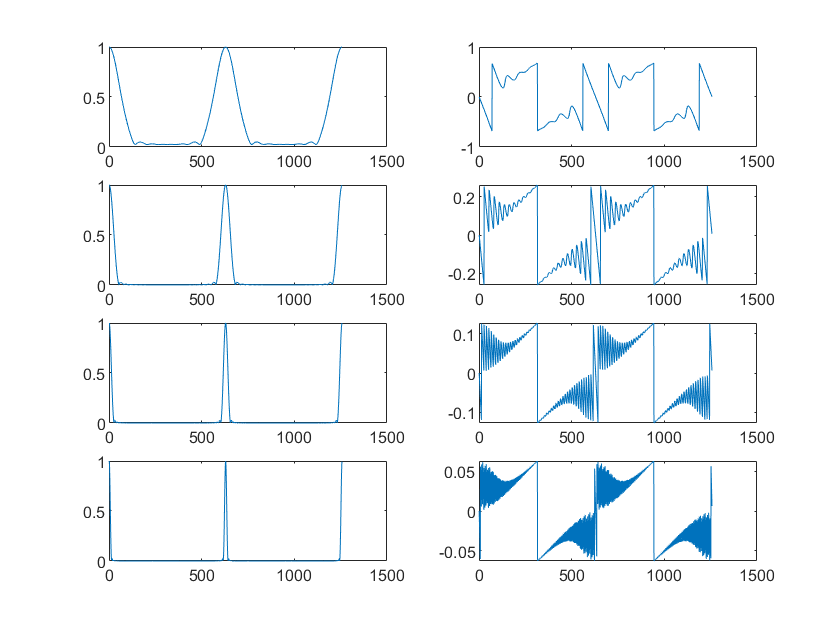

C_10 = 0.5*[1-cos(2*pi*n/9)].*R_10;
C_25 = 0.5*[1-cos(2*pi*n/24)].*R_25;
C_50 = 0.5*[1-cos(2*pi*n/49)].*R_50;
C_101 = 0.5*[1-cos(2*pi*n/100)].*R_101;
figure;
subplot(4,2,1);
title("C10 Magnitude");
plot(abs(dtft(C_10,n,omega))/abs(dtft(C_10,n,[0])));
subplot(4,2,2);
title("C10 Phase");
plot(angle(dtft(C_10,n,omega))/abs(dtft(C_10,n,[0])));
subplot(4,2,3);
title("C25 Magnitude");
plot(abs(dtft(C_25,n,omega))/abs(dtft(C_25,n,[0])));
subplot(4,2,4);
title("C25 Phase");
plot(angle(dtft(C_25,n,omega))/abs(dtft(C_25,n,[0])));
subplot(4,2,5);
title("C50 Magnitude");
plot(abs(dtft(C_50,n,omega))/abs(dtft(C_50,n,[0])));
subplot(4,2,6);
title("C50 Phase");
plot(angle(dtft(C_50,n,omega))/abs(dtft(C_50,n,[0])));
subplot(4,2,7);
title("C101 Magnitude");
plot(abs(dtft(C_101,n,omega))/abs(dtft(C_101,n,[0])));
subplot(4,2,8);
title("C101 Phase");
plot(angle(dtft(C_101,n,omega))/abs(dtft(C_101,n,[0])));

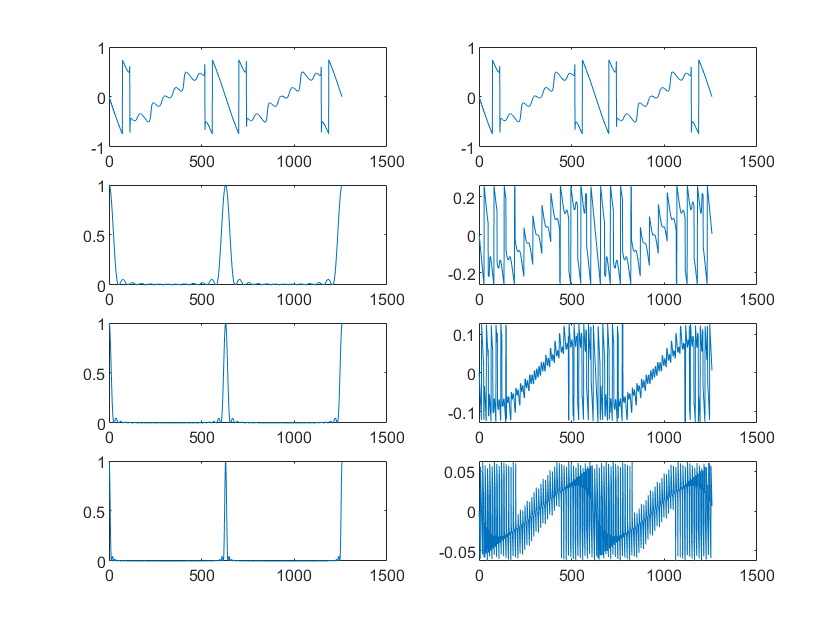

T_10 = [1-abs(10-1-2*n)/9].*R_10;
T_25 = [1-abs(25-1-2*n)/24].*R_25;
T_50 = [1-abs(50-1-2*n)/49].*R_50;
T_101 = [1-abs(101-1-2*n)/100].*R_101;
figure;
subplot(4,2,1);
title("T10 Magnitude");
plot(abs(dtft(T_10,n,omega))/abs(dtft(T_10,n,[0])));
subplot(4,2,2);
title("T10 Phase");
plot(angle(dtft(T_10,n,omega))/abs(dtft(T_10,n,[0])));
subplot(4,2,3);
title("T25 Magnitude");
plot(abs(dtft(T_25,n,omega))/abs(dtft(T_25,n,[0])));
subplot(4,2,4);
title("T25 Phase");
plot(angle(dtft(T_25,n,omega))/abs(dtft(T_25,n,[0])));
subplot(4,2,5);
title("T50 Magnitude");
plot(abs(dtft(T_50,n,omega))/abs(dtft(T_50,n,[0])));
subplot(4,2,6);
title("T50 Phase");
plot(angle(dtft(T_50,n,omega))/abs(dtft(T_50,n,[0])));
subplot(4,2,7);
title("T101 Magnitude");
plot(abs(dtft(T_101,n,omega))/abs(dtft(T_101,n,[0])));
subplot(4,2,8);
title("T101 Phase");
plot(angle(dtft(T_101,n,omega))/abs(dtft(T_101,n,[0])));

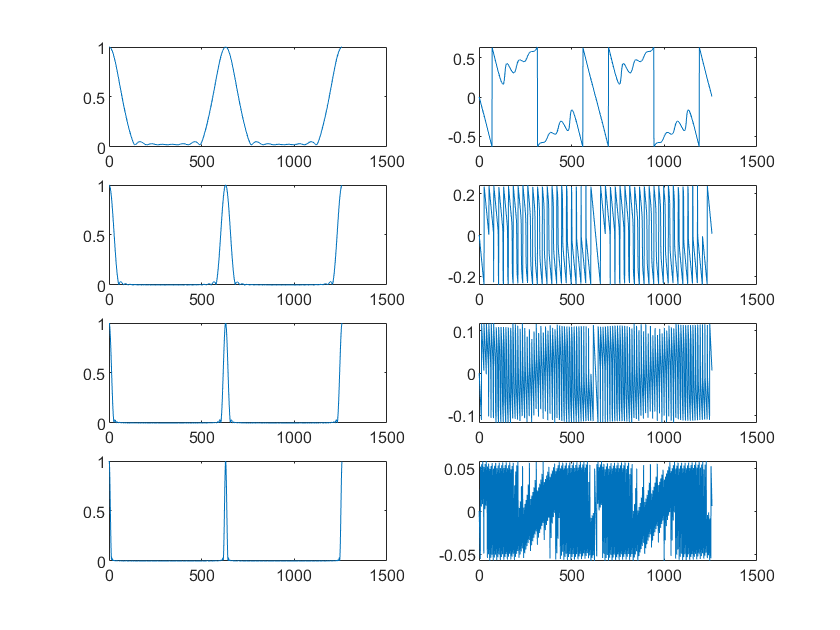

H_10 = [0.54-0.56*cos((2*pi*n)/9)].*R_10;
H_25 = [0.54-0.56*cos((2*pi*n)/24)].*R_25;
H_50 = [0.54-0.56*cos((2*pi*n)/49)].*R_50;
H_101 = [0.54-0.56*cos((2*pi*n)/100)].*R_101;

figure;
subplot(4,2,1);
title("H10 Magnitude");
plot(abs(dtft(H_10,n,omega))/abs(dtft(H_10,n,[0])));
subplot(4,2,2);
title("H10 Phase");
plot(angle(dtft(H_10,n,omega))/abs(dtft(H_10,n,[0])));
subplot(4,2,3);
title("H25 Magnitude");
plot(abs(dtft(H_25,n,omega))/abs(dtft(H_25,n,[0])));
subplot(4,2,4);
title("H25 Phase");
plot(angle(dtft(H_25,n,omega))/abs(dtft(H_25,n,[0])));
subplot(4,2,5);
title("H50 Magnitude");
plot(abs(dtft(H_50,n,omega))/abs(dtft(H_50,n,[0])));
subplot(4,2,6);
title("H50 Phase");
plot(angle(dtft(H_50,n,omega))/abs(dtft(H_50,n,[0])));
subplot(4,2,7);
title("H101 Magnitude");
plot(abs(dtft(H_101,n,omega))/abs(dtft(H_101,n,[0])));
subplot(4,2,8);
title("H101 Phase");
plot(angle(dtft(H_101,n,omega))/abs(dtft(H_101,n,[0])));

# Convolution and Deconvolution as Polynomial Multiplication and Division

Multiply the following two polynomials together using the conv_m.m Matlab function.


$$X_{1}(z) = z + 2 + 3z^{-1}$$



$$X_2(z) = 2z^{2}  + 4z + 3 + 5z^{-1}$$



$$X_3(z) = X_1(z) \cdot X_2(z)$$


Put your code here:

% Convolve x1 and x2
nx1 = [0:60];
nx2 = [0:60];

x1 = [1 2 3];
x2 = [2 4 3 5];
[x3,y] = conv_m(x1,nx1,x2,nx2); %x3 = 2z^4+8z^3+17z^2+23z+19+15z^-1

Write down the polynomial $X_3(z)$ using a latex equation below:

Put your answer here:


$$X(z) = 2z^4+8z^3+17z^2+23z+19+15z^{-1}$$


Divide the following two polynomials using the deconv_m.m Matlab function.


$$X(z) = \frac{z^{2} + z + 1 + z^{-1}+z^{-2} + z^{-3}}{z + 2 + z^{-1}}$$


Put your code here:

% Deconvolve x(z)

xz_num = [1 1 1 1 1 1];
xz_denom = [1 1 1 0 0];
[p,np,r,nr] = deconv_m(xz_num,nx1,xz_denom,nx2);

%quotient p = z, remainder r = z^2 + z + 1

Write down the polynomial $X(z)$ using a latex equation below:

Put your answer here:


$$X(z) = z + \frac{z^2+z+1}{z+2+z^{-1}$$


# Second-order System

The sequence 


$$x[n] = A_{c} (r)^n \cos(\pi\,\nu_{0}\,n)\,u(n) + A_{s} (r)^n \sin(\pi \, \nu_{0}\,n)\,u(n)$$


corresponds to the following Z-Transform


$$X(z) = \frac{b_0 + b_1z^{-1}}{1+a_1z^{-1}+a_2z^{-2}} \ \text{,} \ |z| > |r|$$


where 


$$b_0 = A_c \ \text{;} \ b_1 = r\left[A_s \sin(\pi\,\nu_{0}) - A_c \cos(\pi\,\nu_{0})\right] \ \text{;} \ a_1 = -2r\,\cos(\pi\,\nu_{0}) \ \text{;} \ a_2 = r^2 \ \text{.}$$


Determine the signal parameters $A_c \, \text{,} \ A_s \, \text{,} \ r \, \text{,} \ \nu_{0}$ in terms of the rational function parameters $b_0 \, \text{,} \ b_1 \, \text{,} \ a_1 \, \text{,} \ a_2$ . Write a MATLAB function invCCPP that computes the signal parameters from the rational function parameters. 

You function shoiuld have the form:

function [Ac, As, r, v0] = invCCPP(b0, b1, a1, a2)

Upload this function along with your solution mlx file.

Consider the Z-Transform


$$X(z) = \frac{-2 +5.65z^{-1} -2.88z^{-2}}{1 - 0.1z^{-1} + 0.09 z^{-2} +0.648 z^{-3}}$$


By clever use of the residuez function, express $X(z)$ as:


$$X(z) = \frac{( ) + ()z^{-1}}{1+()z^{-1} + ()z^{-2}} + \frac{()}{1+()z^-1}$$


Use your invCCPP function to determine the causal sequence x[n] corresponding to $X(z)$such that the sequence has no complex numbers in it.

Put your matlab code here:

[residue,poles,K] = residuez([-2 5.56 -2.88],[1 -0.1 0.09 0.648]);


[Qnum,Rnum] = deconv(residue,[1,0,0]);
[Qden,Rden] = deconv(poles,[1,1,0]);

[Ac, As, r, v0] = invCCPP(Rnum(2),Rnum(3),Rden(2),Rden(3));

Write down the sequence x[n] using latex below:


$$x[n] = $$
